# Sourcespace Analysis

This tutorial guides you through the process of performing sourcespace analysis using Beamforming in Fieldtrip. For more background on beamformers, please see this introduction by [Hilliebrand & Barnes (2005)](https://www.sciencedirect.com/science/article/pii/S0074774205680063). 

We will be analysing the same data as analysed in the preprocessing tutorial, involving the presentation of a high contrast visual grating for 1.5s.

## Set-up Paths

The first step will be set up the paths on your machine. 

You will need to following toolboxes, which can be downloaded from Github 

- [Fieldtrip Toolbox](http://www.fieldtriptoolbox.org/)

- [MQ_MEG_Scripts](https://github.com/Macquarie-MEG-Research/MQ_MEG_Scripts)

% Path to the Fieldtrip Toolbox
path_to_fieldtrip       = '/Users/rseymoue/Documents/GitHub/fieldtrip/';
 
% Path to MQ_MEG_Scripts
path_to_MQ_MEG_Scripts  = '/Users/rseymoue/Documents/GitHub/MQ_MEG_Scripts/';

% Add Fieldtrip
addpath(path_to_fieldtrip);
ft_defaults;

% Add MQ_MEG_Scripts
addpath(genpath(path_to_MQ_MEG_Scripts));

## Load Variables Required for Beamforming

We need to load the preprocessed MEG data (`data_clean.mat`) and singleshell headmodel, sourcemodel and transformed MEG sensors made during MRI-MEG coregistration and by `mq_realign_sens`.

% Load preprocessed MEG data
load('data_clean.mat');

% Load singleshell headmodel
load('headmodel.mat');

% Load sourcemodel
load('sourcemodel3d.mat');

% Load transformed MEG sensors
load('grad_trans.mat');

## Band-pass Filter and Select Time-points of Interest

Here we are interested in localising the increase in gamma-band (40-70Hz) power for time-points between 0.3 to 1.5s post-stimulus onset; versus a 1.2s baseline period from -1.5s to -1.3s.

%% BP Filter
cfg             = [];
cfg.bpfilter    = 'yes';
cfg.bpfreq      = [40 70];    %band-pass filter in the required range
data_filtered   = ft_preprocessing(cfg,data_clean);

%% Here we redefine trials based on the time-points of interest.
% Make sure the timepoints are of equivalent length
cfg             = [];
cfg.toilim      = [-1.5 -0.3];
datapre         = ft_redefinetrial(cfg, data_filtered);
cfg.toilim      = [0.3 1.5];
datapost        = ft_redefinetrial(cfg, data_filtered);

## Prepare Leadfield 

By using `ft_prepare_leadfield`, we can compute the forward model for many dipole locations on a 3D sourcemodel and store it for efficient inverse modelling.

%% Create leadfield
cfg             = [];
cfg.channel     = data_clean.label;
cfg.sourcemodel = sourcemodel3d;
cfg.headmodel   = headmodel;
cfg.grad        = grad_trans;
cfg.normalize   = 'yes'; 
lf              = ft_prepare_leadfield(cfg);

% make a figure of the single subject{i} headmodel, and grid positions
figure; hold on;
ft_plot_vol(headmodel,  'facecolor', 'cortex', 'edgecolor', 'none');
alpha 0.5; camlight;
ft_plot_mesh(lf.pos(lf.inside,:));
ft_plot_sens(grad_trans, 'style', 'r*')

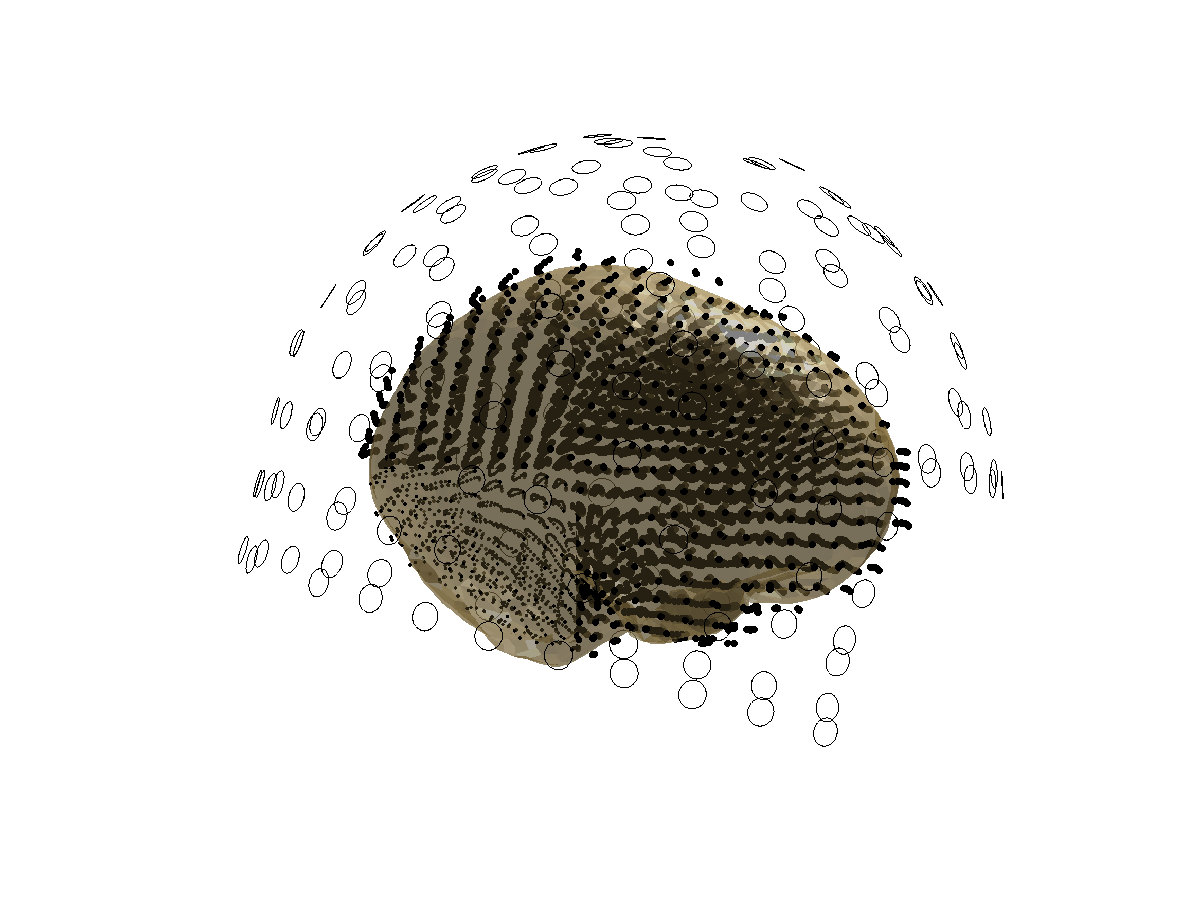

## Compute Covariance Matrix

Fairly self-explanatory!

We also create an AVERAGE covariance matrix for the common spatial filter

%% Compute Covariance Matrix
% ...using ft_timelockanalysis
cfg             = [];
cfg.channel     = data_clean.label;
cfg.covariance  = 'yes';
avgpre          = ft_timelockanalysis(cfg,datapre);
avgpst          = ft_timelockanalysis(cfg,datapost);

% Here we are making an average covariance matrix from the pre and post
% time periods to make a common filter
avg             = avgpst;
avg.cov         = (avgpst.cov + avgpre.cov)/2;

## Source Analysis

Now we can call `ft_sourceanalysis` with the follwing `cfg` options:

%% Do ya beamforming
cfg                     = [];
cfg.channel             = data_clean.label;
cfg.method              = 'lcmv';
cfg.sourcemodel         = lf;
cfg.headmodel           = headmodel;
cfg.lcmv.keepfilter     = 'yes';
cfg.lcmv.lambda         = '5%';
cfg.lcmv.fixedori       = 'yes';
cfg.grad                = grad_trans;
sourceavg               = ft_sourceanalysis(cfg, avg);

% Now do beamforming for the two time points separately using the same spatial
% filter computed from the whole trial
cfg.sourcemodel.filter  = sourceavg.avg.filter; %uses the grid from the whole trial average
%Pre-grating
sourcepreS1             = ft_sourceanalysis(cfg, avgpre);
%Post-grating
sourcepstS1             = ft_sourceanalysis(cfg, avgpst);

## Make sure your field positions match the template grid

In order for the source positions to be consistent across participants, we need to make the `.pos` field equal to the template (MNI) grid. For more information on this, plese see: [LINK](http://www.fieldtriptoolbox.org/example/create_single-subject_grids_in_individual_head_space_that_are_all_aligned_in_brain_atlas_based_mni_space/)

% Load template sourcemodel (8mm)
load([path_to_fieldtrip 'template/sourcemodel/'...
    'standard_sourcemodel3d8mm.mat']);
template_grid       = sourcemodel;
template_grid       = ft_convert_units(template_grid,'mm');
clear sourcemodel;

sourcepreS1.pos     = template_grid.pos; 
sourcepstS1.pos     = template_grid.pos; 

## Calculate Percentage Change

Here we use `ft_math` to keep track of things.

cfg             = [];
cfg.parameter   = 'avg.pow';
cfg.operation   = '((x1-x2)./x2)*100';
sourceR         = ft_math(cfg,sourcepstS1,sourcepreS1);

## Interpolate onto SPM T1 Standard Brain

Interpolate back to the SPM stnadard T1 brain

% Load the SPM T1 brain
mri                 = ft_read_mri([path_to_fieldtrip 'template/anatomy/'...
                    'single_subj_T1.nii']);

cfg                 = [];
cfg.voxelcoord      = 'no';
cfg.parameter       = 'pow';
cfg.interpmethod    = 'nearest';
sourceI             = ft_sourceinterpolate(cfg, sourceR, mri);

## Produce a 2D Plot

Try playing around with the settings of `ft_sourceplot`

%% Produce 2D Plot
cfg                 = [];
cfg.funparameter    = 'pow';
ft_sourceplot(cfg,sourceI);
ft_hastoolbox('brewermap', 1);         % ensure this toolbox is on the path
colormap(flipud(brewermap(64,'RdBu'))) % change the colormap

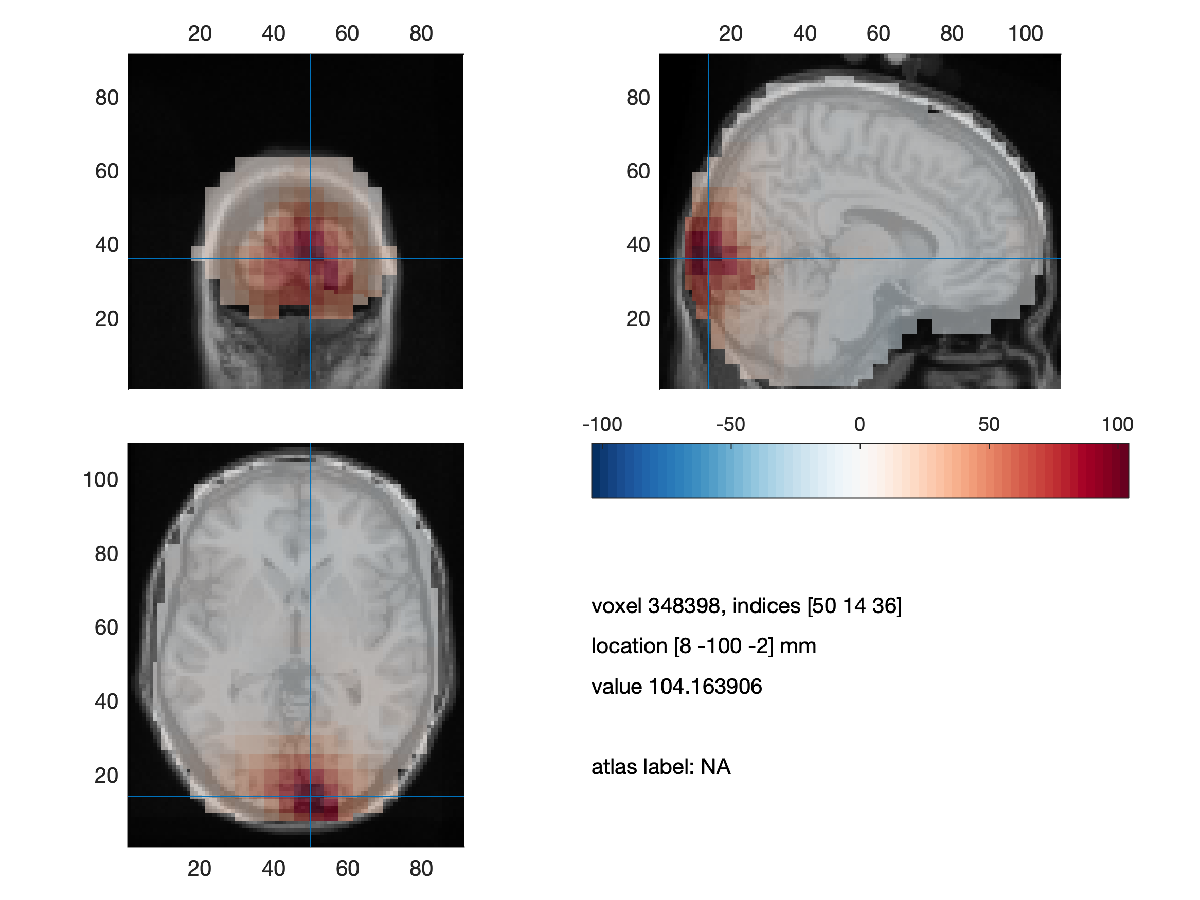

## Produce a 3D Plot

Try playing around with come of the cfg options!

%% Produce 3D Plot
cfg = [];
cfg.method         = 'surface';
cfg.funparameter   = 'pow';
cfg.projmethod     = 'nearest';
cfg.surfinflated   = 'surface_inflated_both.mat';
%cfg.surfdownsample = 10
cfg.projthresh     = 0.2;
cfg.camlight       = 'no';
ft_sourceplot(cfg, sourceI);
ft_hastoolbox('brewermap', 1);         % ensure this toolbox is on the path
colormap(flipud(brewermap(64,'RdBu'))) % change the colormap
light ('Position',[0 0 50])
light ('Position',[0 -50 0])
material dull;
drawnow;
view([0 0]);
title('% Change Gamma Power vs Baseline');
set(gca,'FontSize',14);

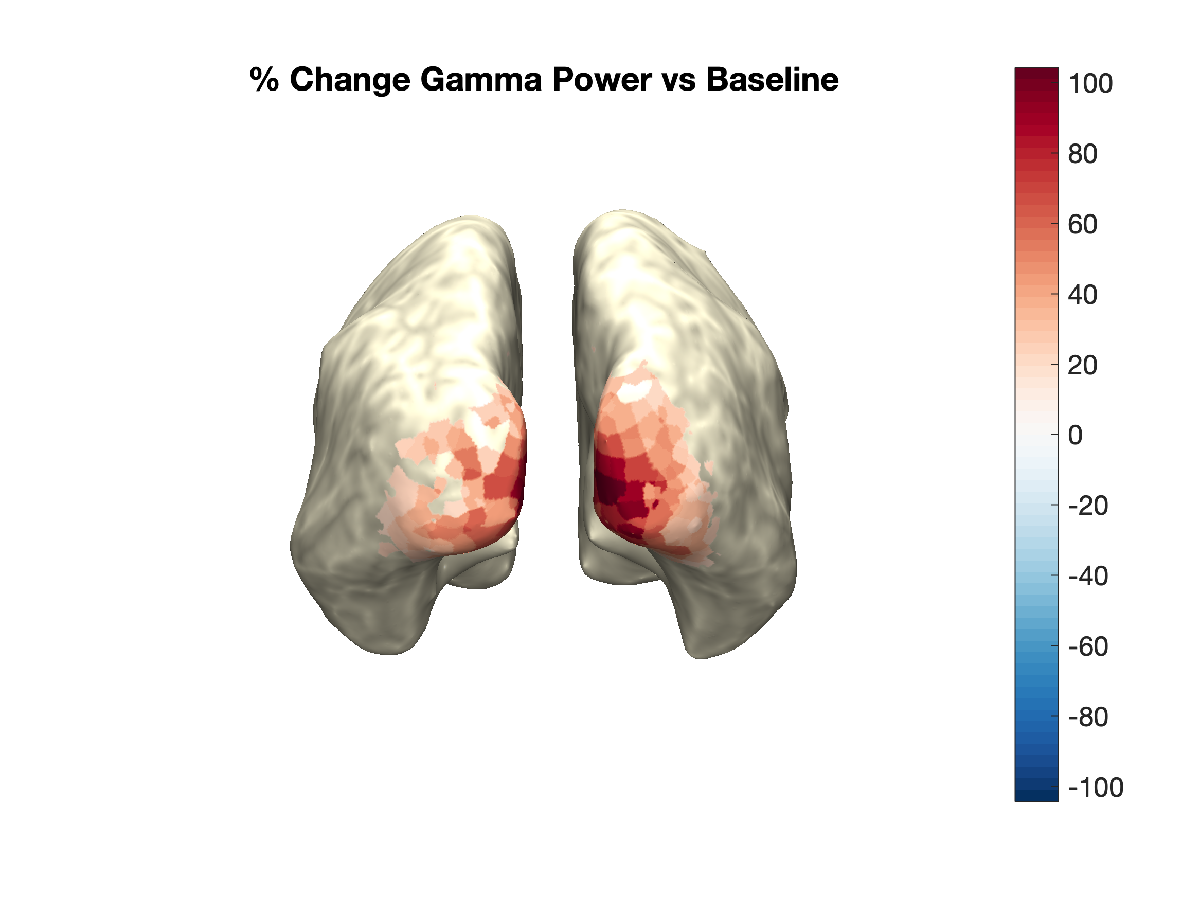

## Create Two Virtual Electrodes Based on the AAL Atlas

Here is some code to create two 'virtual electrodes' or 'virtual channels'. We use the AAL atlas, with ROIs in the left calcarine and right calcarine sulcus.

More technically, this code concatenates all spatial filters within a ROI, multipled by sensor-level data, followed by an SVD. By extracting the first principle component we end up with just ONE filter for each ROI, which we can right-multiply with the sensor-level data.

This is followed by some time-frequency analysis.

% Read in the AAL atlas from Fieldtrip and 
atlas   = ft_read_atlas([path_to_fieldtrip 'template/atlas/aal/ROI_MNI_V4.nii']);
atlas   = ft_convert_units(atlas,'mm');

disp('Creating ROIs in L_Calcarine and R_Calcarine');

% Interpolate the atlas onto 8mm grid
cfg                 = [];
cfg.interpmethod    = 'nearest';
cfg.parameter       = 'tissue';
sourcemodel2        = ft_sourceinterpolate(cfg, atlas, template_grid);

labels = {'Calcarine_L','Calcarine_R'};

for lab = 1:length(labels)
    % Find atlas points
    atlas_points    = find(sourcemodel2.tissue==...
        find(contains(sourcemodel2.tissuelabel,labels{lab})));
    
    % Concatenate spatial filter
    F               = cat(1,sourceavg.avg.filter{atlas_points});
    
    % Do SVD
    [u,s,v]         = svd(F*avg.cov*F');
    filter          = u'*F;
    
    % Create VE
    VE              = [];
    VE.label        = {labels{lab}};
    VE.trialinfo    = data_clean.trialinfo;
    for subs        = 1:(length(data_clean.trialinfo))
        % note that this is the non-filtered "raw" data
        VE.time{subs}       = data_clean.time{subs};
        VE.trial{subs}(1,:) = filter(1,:)*data_clean.trial{subs}(:,:);
    end
    
    % Save to file with label and subject information
    save(sprintf('VE_%s',labels{lab}),'VE');
    
    % Compute TFR using multitapers
    cfg             = [];
    cfg.method      = 'mtmconvol';
    cfg.output      = 'pow';
    cfg.pad         = 'nextpow2'
    cfg.foi         = 1:1:100;
    cfg.toi         = -2.0:0.02:3.0;
    cfg.t_ftimwin   = ones(length(cfg.foi),1).*0.5;
    cfg.tapsmofrq   = ones(length(cfg.foi),1).*8;
    
    multitaper      = ft_freqanalysis(cfg, VE);
    
    % Plot
    cfg                 = [];
    cfg.ylim            = [30 100];
    cfg.xlim            = [-0.5 1.5];
    cfg.baseline        = [-1.5 -0.3];
    cfg.baselinetype    = 'db';
    cfg.zlim            = 'maxabs';
    figure; ft_singleplotTFR(cfg, multitaper);
    title(labels{lab},'Interpreter','none');
    ft_hastoolbox('brewermap', 1);         % ensure this toolbox is on the path
    colormap(flipud(brewermap(64,'RdBu'))) % change the colormap
    xlabel('Time (s)'); ylabel('Frequency (Hz)');
    set(gca,'FontSize',20); drawnow;
    print(sprintf('VE_TFR_%s',labels{lab}),'-dpng','-r200');
end

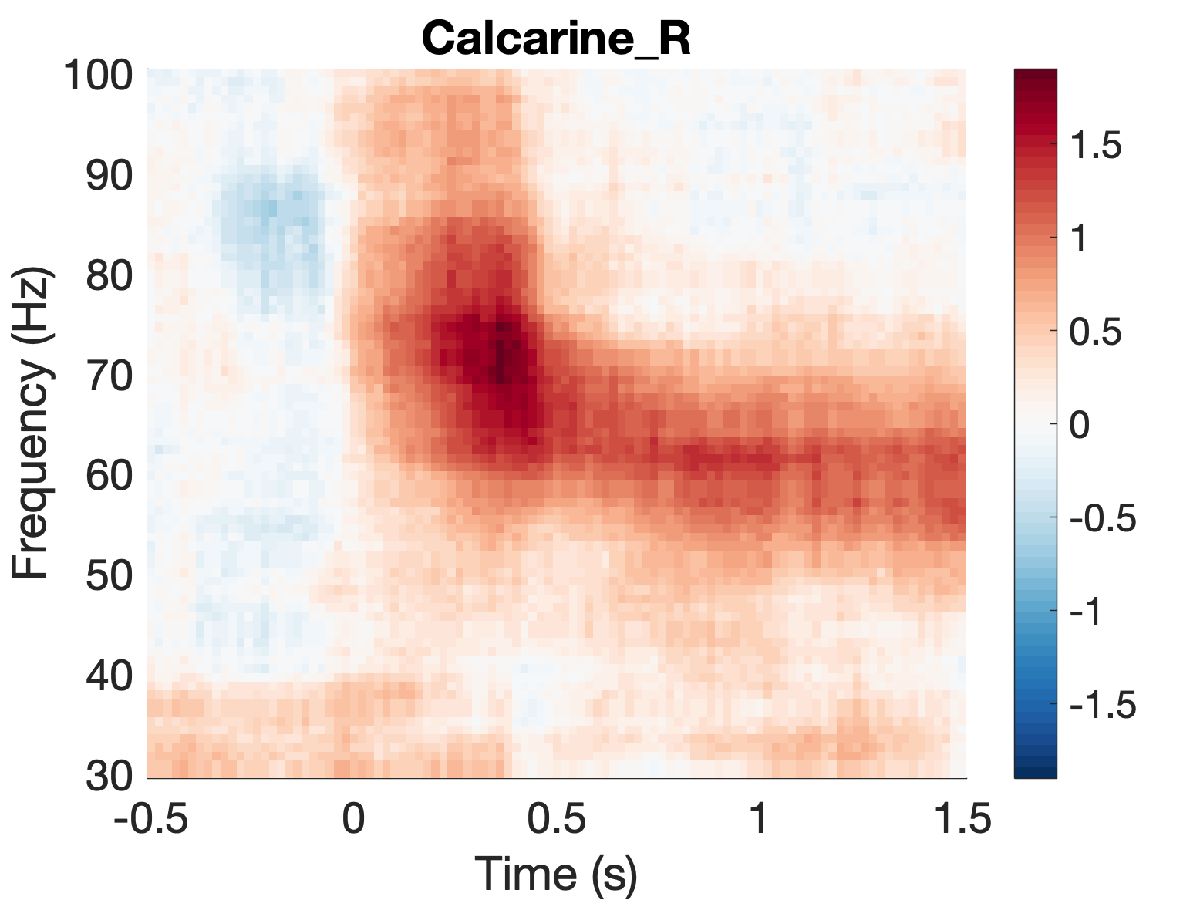

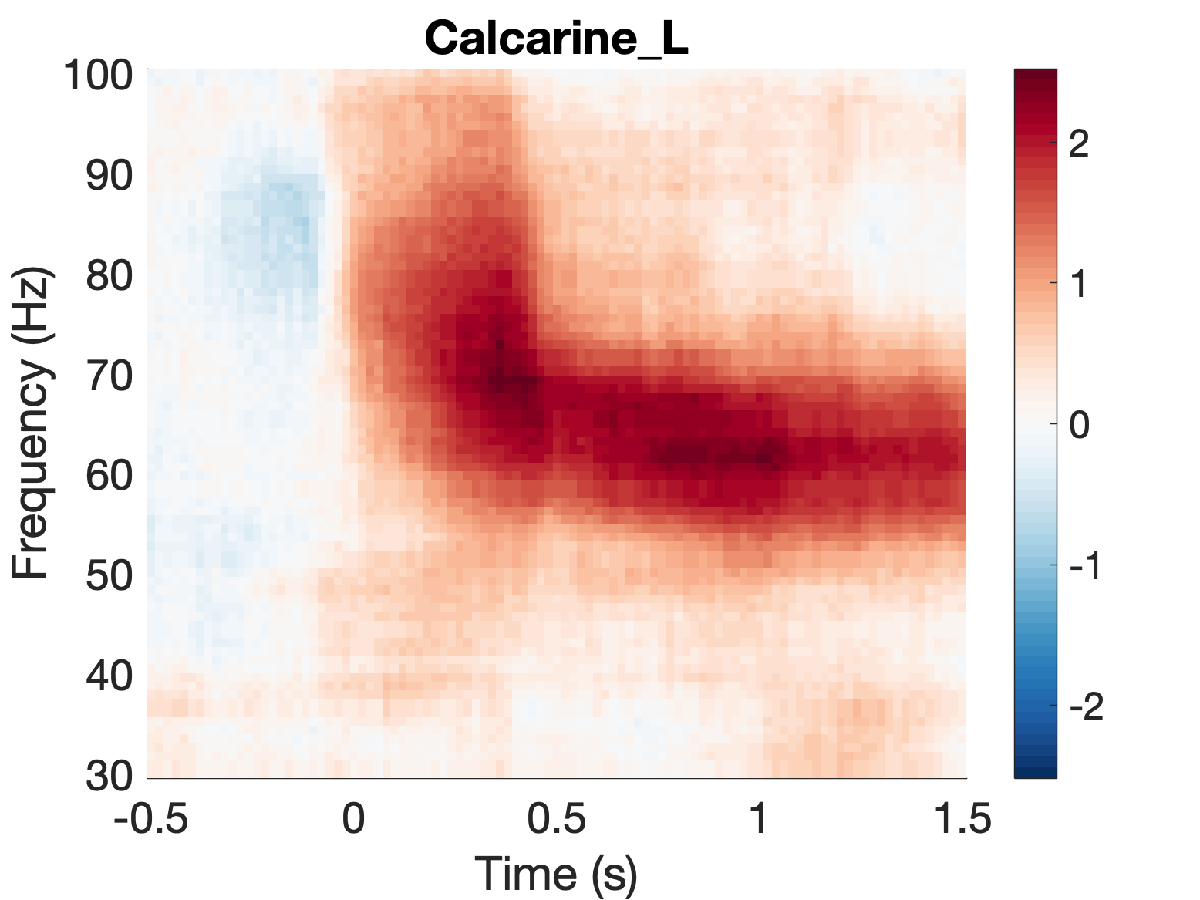

## Group Statistical Analysis

*TO FOLLOW...*